clear
close all
clc

data=xlsread('walkdata.xlsx')

data = 	1.0e+02 *

                   0  -0.291081598900000  -0.051286073300000   0.128153005900000   0.115358763800000  -0.006225158300000  -0.046141790400000   0.006121349400000   0.010179025000000
   0.010000000000000  -0.291082805700000  -0.069517633000000   0.128238003700000   0.122223238500000  -0.029617173400000  -0.056538123800000   0.006130329800000   0.010165978000000
   0.020000000000000  -0.289898820000000  -0.088866148200000   0.125224119200000   0.127708324700000  -0.052361015100000  -0.065531986600000   0.006145626200000   0.010155183900000
   0.030000000000000  -0.285513833200000  -0.114085183900000   0.120820825400000   0.133742399100000  -0.076951273100000  -0.071478634400000   0.006161287100000   0.010147881000000
   0.040000000000000  -0.283407902500000  -0.142706867400000   0.110774807400000   0.134981894800000  -0.103383851000000  -0.071036285500000   0.006184457900000   0.010151609600000
   0.050000000000000  -0.274743079700000  -0.178920803800000   0.09778090670

t=data(:,1);
Rhip=data(:,2);
Rknee=data(:,3);
Rankle=data(:,4);

Lhip=data(:,5);
Lknee=data(:,6);
Lankle=data(:,7);

[Rhipf, info]=RhipFit(t,Rhip)

Rhipf =      Linear interpolant:
       Rhipf(x) = piecewise polynomial computed from p
       where x is normalized by mean 75 and std 43.73
     Coefficients:
       p = coefficient structure

info = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


t=0:0.1:150

t = 	1.0e+02 *

                   0   0.001000000000000   0.002000000000000   0.003000000000000   0.004000000000000   0.005000000000000   0.006000000000000   0.007000000000000   0.008000000000000   0.009000000000000   0.010000000000000   0.011000000000000   0.012000000000000   0.013000000000000   0.014000000000000   0.015000000000000   0.016000000000000   0.017000000000000   0.018000000000000   0.019000000000000   0.020000000000000   0.021000000000000   0.022000000000000   0.023000000000000   0.024000000000000   0.025000000000000   0.026000000000000   0.027000000000000   0.028000000000000   0.029000000000000   0.030000000000000   0.031000000000000   0.032000000000000   0.033000000000000   0.034000000000000   0.035000000000000   0.036000000000000   0.037000000000000   0.038000000000000   0.039000000000000   0.040000000000000   0.041000000000000   0.042000000000000   0.043000000000000   0.044000000000000   0.045000000000000   0.046000000000000   0.047000000000000   0.048000000000000   0

Rh=Rhipf(t)

Rh =  -29.108159890000000
 -29.108171958000000
 -29.108184026000000
 -29.108196094000000
 -29.108208162000000
 -29.108220230000001
 -29.108232298000001
 -29.108244366000001
 -29.108256434000001
 -29.108268502000001


dRh=diff(Rhipf(t))

dRh =   -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000
  -0.000012068000000


ddRh=diff(diff(Rhipf(t)))

ddRh =                    0
                   0
                   0
                   0
                   0
                   0
                   0
                   0
                   0
   0.011851924999998


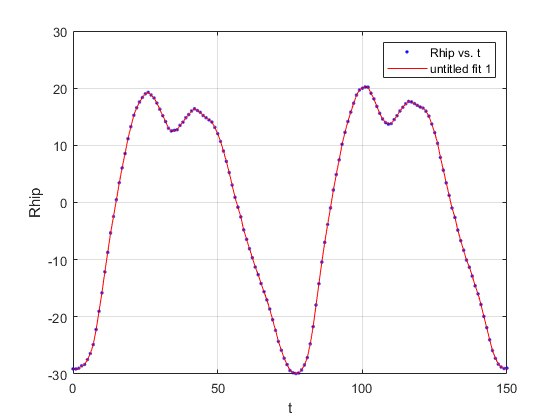


grid on

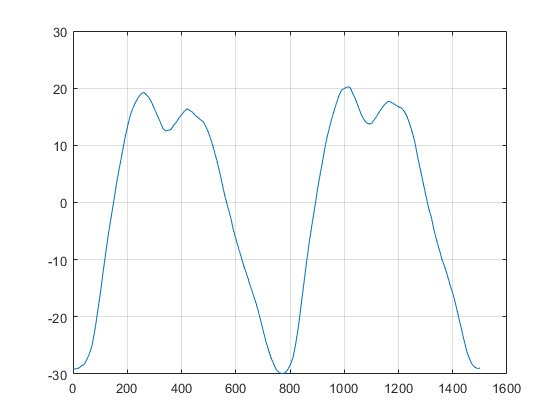

plot(Rh)
grid on

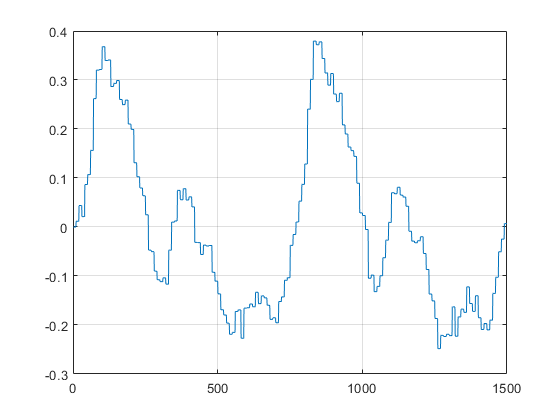

plot(dRh)
grid on

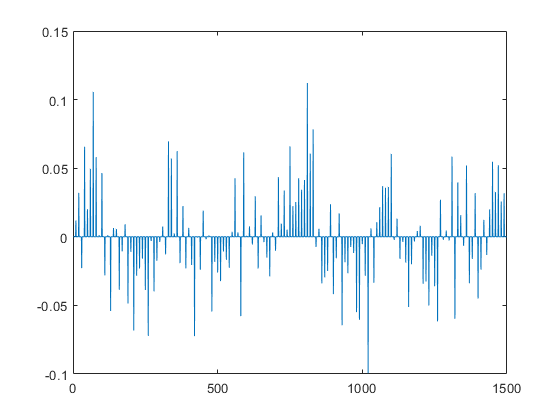

plot(ddRh)